# DonkeyCar's Dataset Replay using MATLAB/Simulink

## Introduction

[DonkeyCar](https://www.donkeycar.com/) is an open source AI car that uses Python based TensorFlow and Keras as a deep learning framework. This is an example of DoneyCar's Dataset Replay and Prediction by deep learning model.

## Required Tools

- MATLAB 2021B or later

- [Deep Learning Toolbox](https://jp.mathworks.com/products/deep-learning.html) 

- [MATLAB Support Package for Raspberry Pi](https://jp.mathworks.com/help/supportpkg/raspberrypiio/) Add-On (No Raspberry-PI hardware required. Only use for video display)

## Replay a dataset using a deep learning predictive model

Use the dataset published on GitHub.

[https://github.com/autorope/donkey_datasets/tree/master/circuit_launch_20210716](https://github.com/autorope/donkey_datasets/tree/master/circuit_launch_20210716)

Use the following * .h5 file (Keras model) as the base data planning model.

[https://github.com/autorope/donkey_datasets/tree/master/circuit_launch_20210716/models](https://github.com/autorope/donkey_datasets/tree/master/circuit_launch_20210716/models)

## Data preparation

### Dataset download

Execute the following MATLAB script to download the DonkeyCar dataset file (* .gz) from GitHub and unzip it under the current folder.

%Download DonkeyCar dataset on GitHub
% url = 'https://github.com/autorope/donkey_datasets/raw/master/circuit_launch_20210716/';%Original URL
% tarfile = 'circuit_launch_20210716_1826.tar.gz'; %Original data
url = 'https://github.com/covao/donkey_dataset_example/raw/main/';
tarfile = 'circuit_launch_20210716_1826_no4.tar.gz'; %Recompress only No4 data

datapath = './murmurpi4_circuit_launch_20210716_1826/data/';%Data Path

if(~exist(datapath,'file')) %if not unzipped
    disp('Wait a few minutes for downloading and unziping.')
    websave('temp.gz',[url tarfile],weboptions('Timeout',Inf));
    untar('temp.gz');
end


## Download pre-learned deep learning models

Download Donkey Car's pre-trained deep learning model file (Keras).  pilot_21-08-12_10.h5

%Download Donkeycar deep learning mode
url = 'https://github.com/autorope/donkey_datasets/raw/master/circuit_launch_20210716/';
netfile='pilot_21-08-12_10.h5';
websave(netfile,[url 'models/' netfile]);


## Loading a pretrained model

Load the model into the workspace.

donkeyKerasNet = importKerasNetwork(netfile); %Load pre-trained network
save donkeyKerasNet;


## Read catalog file

A list of DonkeyCar driving data is recorded in the * .catalog file. Load the dataset containing the image data file name, steering value, and throttle value into MATLAB. Here, read catalog_4.catalog.

%Import catalog
catalogfile = [datapath 'catalog_4.catalog'];%Catalog file
clear dataset;
js = readlines(catalogfile);
for(i = 1:length(js)-1)
    dataset(i) = jsondecode(js(i));
end

%Set image path
imgfolder = [datapath 'images/'];
imgfiles = {dataset.cam_image_array};
imgpath = {};
for(i = 1:length(imgfiles))
    imgpath{i} = strcat(imgfolder,imgfiles{i});
end


## Create Signal Structure

%Create Signal Structure for Simulink
ti = [dataset.x_timestamp_ms]';
ti = (ti-ti(1))/1000;

SigSteering.time = ti;
SigSteering.signals.dimensions = 1;
SigSteering.signals.values = [dataset.user_angle]'

SigThrottle.time = ti;
SigThrottle.signals.dimentions = 1;
SigThrottle.signals.values = [dataset.user_throttle]';


## Create Image Signal Structure

%Create Image Array
for(i=1:length(imgpath))
    img(:,:,:,i)=imread(imgpath{i});
end

%Create Image Signal Structure for Simulink
SigImage.time = ti;
SigImage.signals.dimensions=[120 160 3];
SigImage.signals.values = img;


## Open Simulink Model

open('donkeycar_replay.mdl');


## 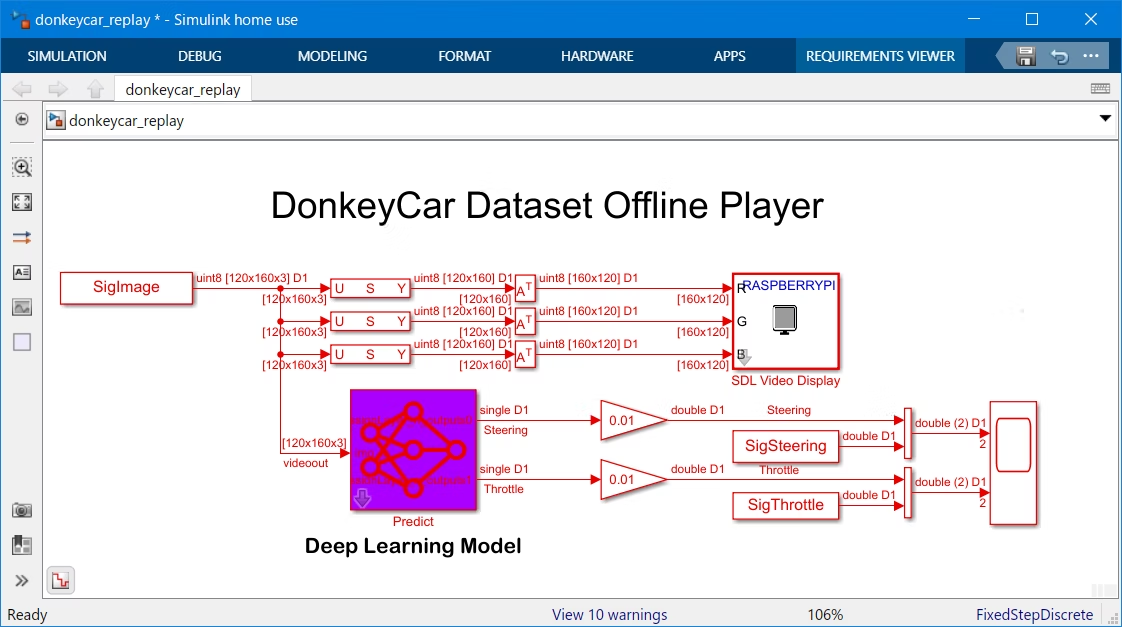

## Run Simulink Model

## 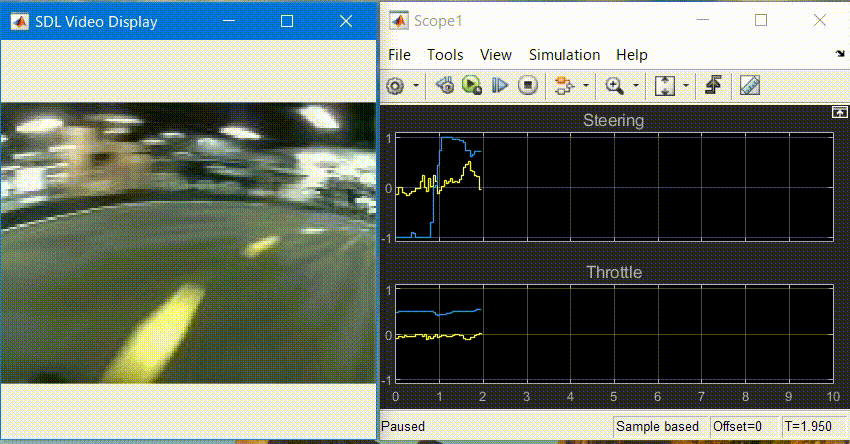

## Reference

- [DonkeyCar](https://www.donkeycar.com/)

- [Donkey Car User Guide>Dataset and pre-trained models](https://docs.donkeycar.com/guide/dataset_pretrained_models/)

- [Implementing Network Lag for Keras Linear with DonkeyCar](https://handykurniawan.medium.com/implementing-network-lag-for-keras-linear-with-donkeycar-43fd726c2afe)